clc;clear;close all;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-fibnVSdelay.mat'), ...
    'IEDtwDas', 'fibNas');
[forest, tf, scores] = iforest([fibNas, IEDtwDas], "ContaminationFraction", 0.1);
fibNas = fibNas(scores <= forest.ScoreThreshold);
IEDtwDas = IEDtwDas(scores <= forest.ScoreThreshold);
[r, p] = corr(fibNas, IEDtwDas);
disp(r);disp(p);

   -0.2551

     0



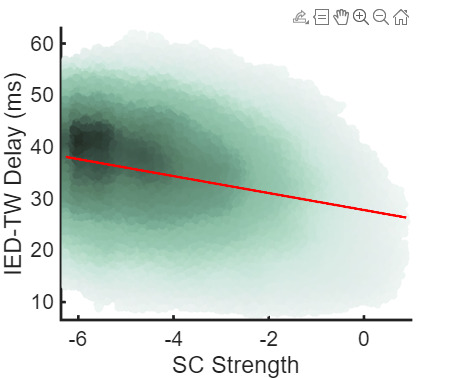

[~, Curve, ~] = f_polyfit(fibNas, IEDtwDas, 1);
figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
f_densityScatter(fibNas, IEDtwDas, 1); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(fibNas)-0.1, max(fibNas)+0.1]); 
ylim([min(IEDtwDas)-1, max(IEDtwDas)+1]);
xlabel('SC Strength'); ylabel('IED-TW Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

clc; clear; close all;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-fibnVSdelay.mat'), 'R_fibNtwD_as');
R_fibNtwD_true = R_fibNtwD_as;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtwNull_meth-none_TD-6d0_polyfit-fibnVSdelay.mat'), 'R_fibNtwD_as')
R_fibNtwD_null = mean(R_fibNtwD_as, 1);
disp(mean(R_fibNtwD_true(:)));

   -0.2304



disp(std(R_fibNtwD_true(:)));

    0.0082



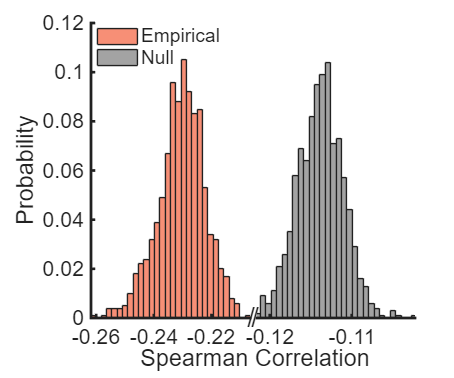

figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
Ax1 = axes; set(Ax1, 'Position', [0.2, 0.16, 0.35, 0.78]);
histogram(R_fibNtwD_true(:), 30, 'FaceColor', [0.95, 0.27, 0.1], ...
    'Normalization', 'probability');
xlim([min(R_fibNtwD_true(:)), max(R_fibNtwD_true(:))]); 
ylim([0, 0.12]);
xlabel('Spearman Correlation', 'Position', [-0.205, -0.011]);  ylabel('Probability');
annotation('textbox', [0.502, 0.105, 0.1, 0.1], 'String', '/', ...
           'EdgeColor', 'none', 'FontSize', 20, ...
           'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
annotation('textbox', [0.511, 0.105, 0.1, 0.1], 'String', '/', ...
           'EdgeColor', 'none', 'FontSize', 20, ...
           'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
set(Ax1, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
Ax2 = axes; set(Ax2, 'Position', [0.565, 0.16, 0.35, 0.78]);
histogram(R_fibNtwD_true(:), 30, 'FaceColor', [0.95, 0.27, 0.1], ...
    'Normalization', 'probability'); hold on;
histogram(R_fibNtwD_null(:), 30, 'FaceColor', [0.4, 0.4, 0.4], ...
    'Normalization', 'probability'); hold off;
xlim([min(R_fibNtwD_null(:)), max(R_fibNtwD_null(:))]); 
ylim([0, 0.12]);
legend(["Empirical", "Null"], "Box", "off", "Position", [0.2074 0.8144 0.2863, 0.1230]);
set(Ax2, 'YColor', 'none', 'ytick', [], 'yticklabel', [], ...
    'Box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

x = R_fibNtwD_true(:); y = R_fibNtwD_null(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval; cliffDelta = f_cliff_delta(x, y);
df = length(x) + length(y) - 2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 0 z = -38.7201 Cliff Delta = -1 df = 1998


clc;clear;close all;
addpath z_toolbox\Violinplot
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-fibnVSdelay.mat'), 'R_fibNtwD');
R_fibNtwD_true = R_fibNtwD';
R_fibNtwD_true(R_fibNtwD_true==0) = [];
trueStr = cell(length(R_fibNtwD_true), 1);
for n = 1:length(trueStr)
    trueStr{n} = 'Empirical';
end
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtwNull_meth-none_TD-6d0_polyfit-fibnVSdelay.mat'), 'R_fibNtwD');
R_fibNtwD_null = mean(R_fibNtwD, 2);
R_fibNtwD_null(R_fibNtwD_null==0) = [];
nullStr = cell(length(R_fibNtwD_null), 1);
for n = 1:length(nullStr)
    nullStr{n} = 'Null';
end
R = [R_fibNtwD_true; R_fibNtwD_null];
Origin = [trueStr; nullStr];
disp(mean(R_fibNtwD_true));

   -0.2508



disp(std(R_fibNtwD_true));

    0.0764



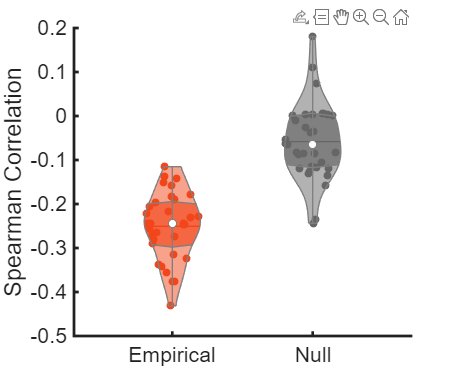

figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
vs = violinplot(R, Origin, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Empirical', 'Null'}, ...
    'ViolinColor', [0.95, 0.27, 0.1; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]); ylabel('Spearman Correlation');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

x = R_fibNtwD_true(:); y = R_fibNtwD_null(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval; cliffDelta = f_cliff_delta(x, y);
df = length(x) + length(y) - 2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 8.6305e-11 z = -6.4892 Cliff Delta = -0.93021 df = 64
